clear
load data3.mat
n=length(data.CzasLokalnyUTC0100);
data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   2024-05-20 23:00:00
   2024-05-20 23:01:00
   2024-05-20 23:02:00
   2024-05-20 23:02:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   2024-05-23 01:57:00
   2024-05-23 01:58:00
   2024-05-23 01:59:00
   2024-05-24 02:00:00


T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);
Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;
X=Wlot;
compressor=data.StanKompresor;
[X,nan_indices]  = GetRidOfNans(X);

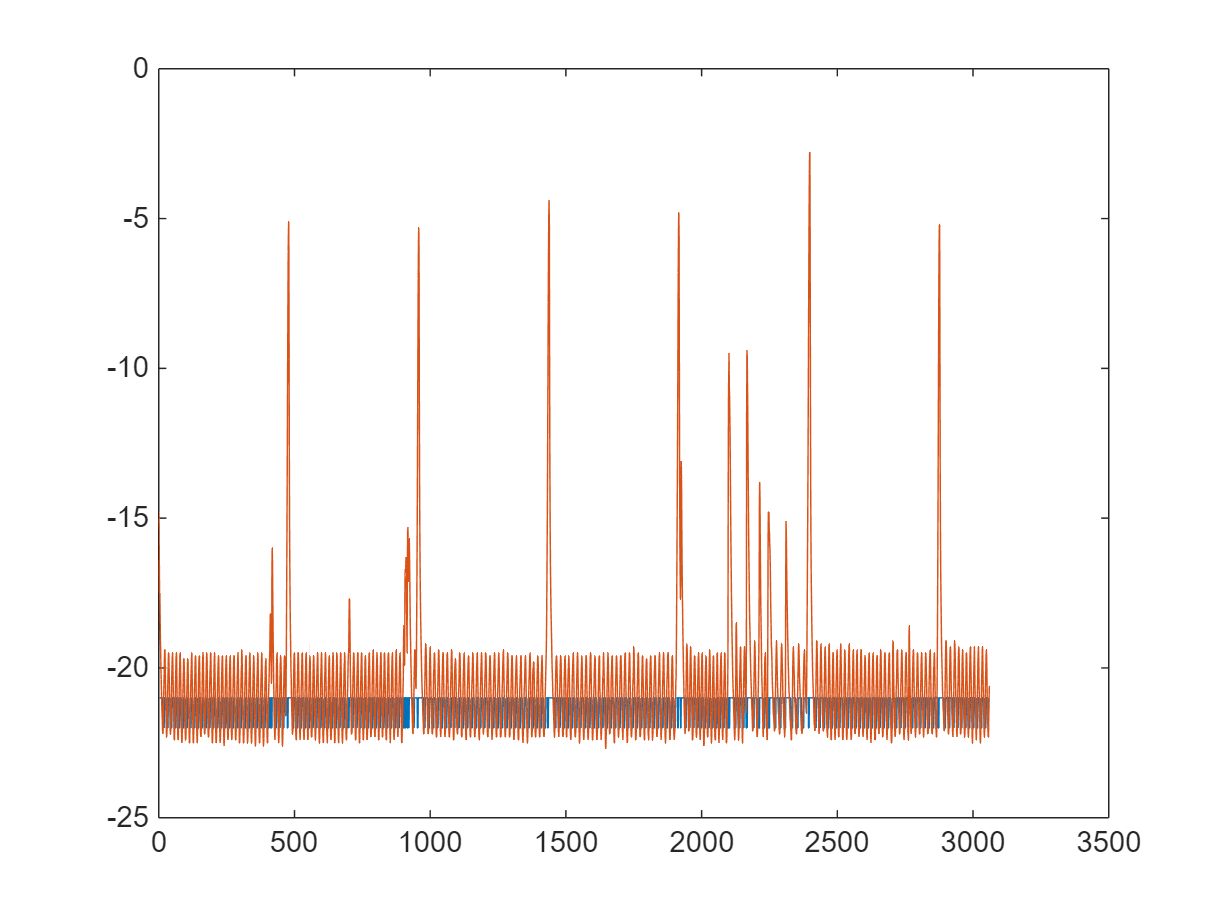

figure
plot(-22.+compressor);hold on;
plot(X);

We see that there is a temporal shift betwee the temperature peak and compressor turning on

There is a temporal shift between the valley of the temp and the compresor turning off.

Ideally the shift on the peak would equal the shift of the valley. In this dataset it is pretty close, hence the peak detection algo had better results than the graybox.

The idea here could be:

Assuming we know:

physical parameters like compressor efficiency, tharmal isolation and themral mass (load)

We can:

Run a simulation and get the supposed

## Remooving anomalies


anomaly_locs=compressorCycles(Kompresor1);%for operating on anomaly

compressor_locs=anomaly_locs;%for operating on all locs


features = FeatureExtract(X,anomaly_locs);
f1=zeros(1,length(anomaly_locs)-1);
for i=1:length(anomaly_locs)-1
    f1(i)=anomaly_locs(i+1)-anomaly_locs(i);
end
anomaly_locs=anomaly_locs(2:end);
fridge_air_temp_p2p=features(1,:)-features(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
for i=2:length(features)
    
    if (TF(i)==0)
        indexContainer{set}=[indexContainer{set},anomaly_locs(i-1):anomaly_locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end

### Setting proper index container length 

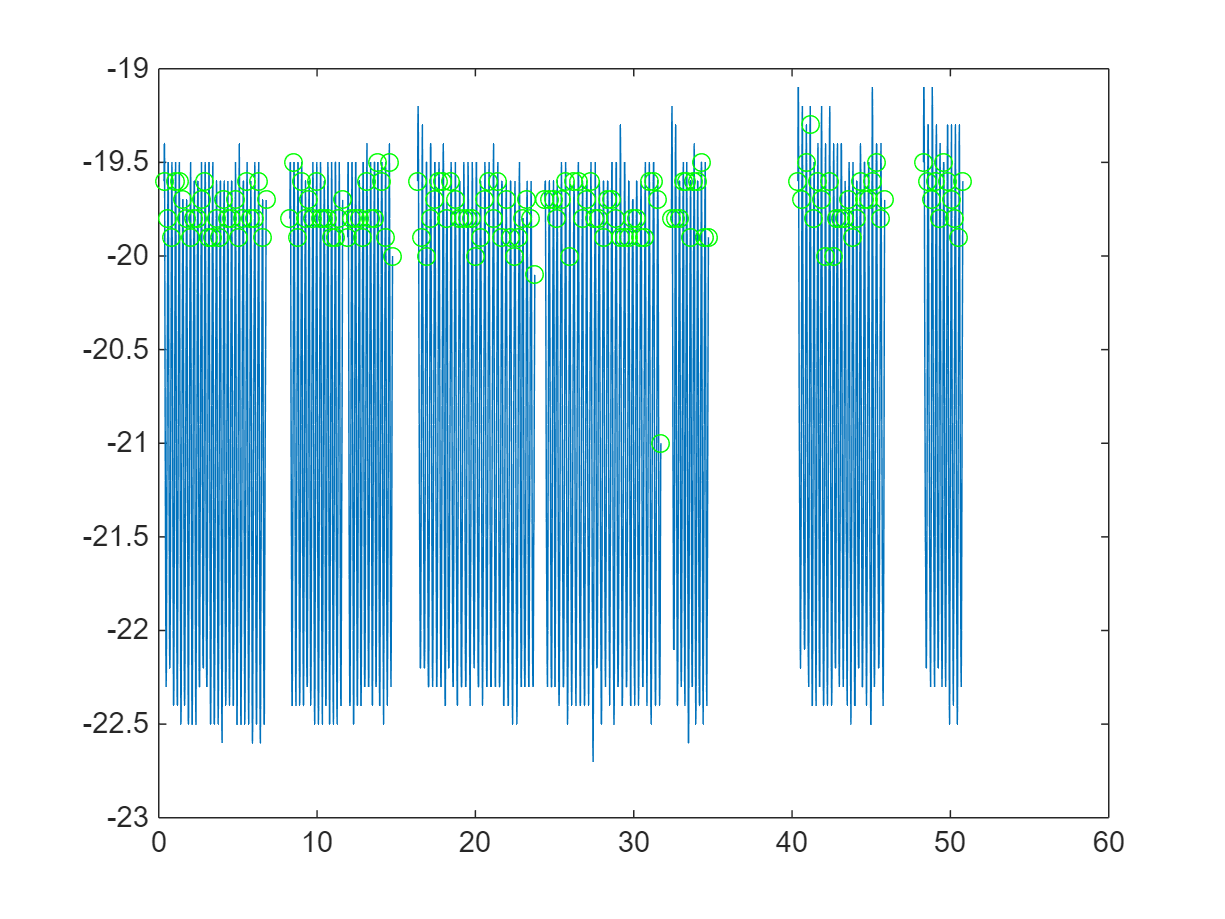

set=1;
usableDataIndex_length = 0;

clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*60*2*fs
        usableDataIndex{set}=indexContainer{i};
        usableDataIndex_length = usableDataIndex_length + length(indexContainer{i});
        set=set+1;
    end
end

%extracts compressor locs but only the ones present in usableDataIndex
compressor_locs=compressor_locs(ismember(compressor_locs, [usableDataIndex{:}]));

figure
for i = 1:length(usableDataIndex)
    plot(t(usableDataIndex{i})/60/60,X(usableDataIndex{i}),"Color","#0072BD");hold on
    plot(t(compressor_locs)/60/60, ...
        X(compressor_locs),'o',"Color","#00FF00")
end

% load MergeAlgo_data3.mat
y=cell(1,length(usableDataIndex));
params=cell(1,length(usableDataIndex));
% parfor i = 1:length(usableDataIndex)
for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    [y{i},params{i}]=GATrain(compressor(usableDataIndex{i})', TemperaturaOtoczenia(usableDataIndex{i})',...
        t_sim, X(usableDataIndex{i}(1)), X(usableDataIndex{i}))';
end

Error using makeState (line 67)
Your fitness function must return a scalar value.

Error in gaunc (line 47)
state = makeState(GenomeLength,FitnessFcn,Iterate,output.problemtype,options);

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('ga', 'C:\Program Files\MATLAB\R2024b\toolbox\globaloptim\globaloptim\ga.m', 417)" style="font-we


save MergeAlgo_data3 y params

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

TrainingFraction=0.3;  % percent of dataset used for training
TrainingNumber=floor(TrainingFraction*length(usableDataIndex));
TrainingData=usableDataIndex(1:TrainingNumber);
TestingData=usableDataIndex(TrainingNumber+1:end);

figure
hold on
for i = 1:length(TrainingData)
% for i = 1:3
    plot(t(TrainingData{i})/(60*60),X(TrainingData{i}),'Color','#D95319')
    plot(t(TrainingData{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

for i = 1:length(params)
resu(i,:)=params{i};
end


% figure
% plot3(resu(:,1),resu(:,2),resu(:,3),'o');
% grid on
% xlabel('G')
% ylabel('R')
% zlabel('C')
% title('Plot of parameter value results')
% % view(0,0)
% view(0,90)

Results analysys

for i = 1:length(TrainingData)
rmse_mat(i)=rmse(X(TrainingData{i})',y{i});
end

[rmse_mat_sorted, sort_indeces] = sort(rmse_mat);

% function bestParameter=bestOfDataSet(TrainingSet,params,T)
TrainingSet=TrainingData;


averageRMSE=NaN(1,length(TrainingSet));
parfor j=1:length(TrainingSet) %for parameter set j
    RMSE_on_all=NaN(1,length(TrainingSet));
    for i=1:length(TrainingSet) %check rmse of j parameter set on all data chinks
        t_sim=T*(0:length(usableDataIndex{i})-1);
        RMSE_on_all(i) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{j}(1), params{j}(2), params{j}(3),...
            t_sim, X(usableDataIndex{i}(1)), X(usableDataIndex{i}));
    end

    if any(isnan(RMSE_on_all), 'all')
        error('Array RMSE_on_all contains NaN values.');
    end

    averageRMSE(j)=mean(RMSE_on_all); %average rmse for j parameter set on all data chunks

end

if any(isnan(averageRMSE), 'all')
    error('Array averageRMSE contains NaN values.');
end

[~,ind] = min(averageRMSE);
bestParameter=params(ind);


figure
hold on
for i = 1:TrainingNumber
% for i = 1:3
    t_sim=T*(0:length(TrainingData{i})-1);
    y_tmp=ModelFunction(-X(2,TrainingData{i})', X_filtered(1,TrainingData{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X(TrainingData{i}(1)))';

    plot(t(TrainingData{i})/(60*60),X(TrainingData{i}),'Color','#D95319')
    plot(t(TrainingData{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

figure
hold on
for i = TrainingNumber+1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X(usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X(usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

min(averageRMSE)
clear RMSE_on_all_testing
count=1;
for i=TrainingNumber+1:length(usableDataIndex)
    t_sim=T*(0:length(usableDataIndex{i})-1);
    RMSE_on_all_testing(count) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
        params{ind}(1), params{ind}(2), params{ind}(3),...
        t_sim, X(usableDataIndex{i}(1)), X(usableDataIndex{i}));
   count=count+1;
end
mean(RMSE_on_all_testing)
(mean(RMSE_on_all_testing)-min(averageRMSE))/min(averageRMSE)

So the rmse on testing is 18% worst than on training 

figure
hold on
count=1;
for i = TrainingNumber+1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X(usableDataIndex{i}(1)))';

    simData = fridge_fixed_stepCopy(X_filtered(1,usableDataIndex{i})',params{ind}(1), params{ind}(2), params{ind}(3),t_sim,X(usableDataIndex{i}(1))');
    plot(t(usableDataIndex{i})/(60*60),simData.y,'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),X(usableDataIndex{i}),'Color','#0072BD')
    compare_container.mask_pred{count}=simData.u1;
    compare_container.mask_meas{count}=-X(2,usableDataIndex{i});
    count=count+1;
    % plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
    clear simData
end
hold off
title('Best model with Compressor logic on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model with Compressor logic')

for i=1:length(compare_container.mask_pred)
stats(i) = compareOnTime(compare_container.mask_pred{i}, compare_container.mask_meas{i});
v(i)=stats(i).pctError;
end
mean(abs(v))

results = analyzeCompressorMaskFromGrayBox(compare_container,'plot',false);
pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')
histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')
idx_badResults = find(abs(pctErrorVector) > 10)

7 results with error > 10%

fprintf('\n=== Data Quality / Error Summary ===\n');
fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

## Now let's see how indentifying the offset between the compressor state change and temperature peak impacks our simple algo

Let's take one chunk:

plot(X(2,TrainingData{1}));hold on
plot(X(TrainingData{1}));hold off

We identify the peaks and valleys and select a offset that will minimise the error

results = analyzeCompressorSegments( ...
    t, X, X(2,:), usableDataIndex(1), ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

Above without offset

Below we find the optimal offset

calib = estimatePeakValleyOffsetsFromLabels(t, X, X(2,:), usableDataIndex(1))

We use the optimal offset below

results = analyzeCompressorSegments( ...
    t, X, X(2,:), usableDataIndex(1), ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);

We get best coverage

Sanity check: On training without offset calibration:

results = analyzeCompressorSegments( ...
    t, X, X(2,:), TrainingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);
pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')
histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')
idx_badResults = find(abs(pctErrorVector) > 10);
length(idx_badResults)
fprintf('\n=== Data Quality / Error Summary ===\n');
fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));
fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));


On  training with calibration

clear calib
clear results
calib = estimatePeakValleyOffsetsFromLabels(t, X, X(2,:), TrainingData)
results = analyzeCompressorSegments( ...
    t, X, X(2,:), TrainingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')
histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')
idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)
fprintf('\n=== Data Quality / Error Summary ===\n');
fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));
fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

The MAPE is bigger on the calibrated set than on the set without offset

## Now trying the MAPE on testing with vs without calibration:

results = analyzeCompressorSegments( ...
    t, X, X(2,:), TestingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);
pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)
fprintf('\n=== Data Quality / Error Summary ===\n');
fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));
fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

results = analyzeCompressorSegments( ...
    t, X, X(2,:), TestingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);
pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)
fprintf('\n=== Data Quality / Error Summary ===\n');
fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));
fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

function simData = fridge_fixed_stepCopy(Ta,G,R,c,t,x0)
% Discrete-time simulation of a refrigerator with hysteresis control
% ––– USER DEFINED SYSTEM ––– ------------------------------------------

% G=2.1686;   
% R=48.9120; 
% c=114.2959;

A=-1/(R*c);
B=[G/c,1/(R*c)];
C=1;
D=[0,0];

dt     = t(2)-t(1);                % time step [s]
Tend   = t(end);           % simulate 2 hours
% t      = 0:dt:Tend;        % time vector
Ta_fun = @(t) Ta((t/dt)+1);  % outdoor temperature

n   = size(A,1);
x   = zeros(n,length(t));
% x0  = zeros(n,1);         % initial state
x(:,1) = x0;

y  = zeros(1,length(t));
u1 = zeros(1,length(t));
u2 = arrayfun(Ta_fun, t);

% ––– Hysteresis controller state
heater = 0;               % compressor OFF initially
T_low  = -22;               % °C, turn ON below this
T_high = -20;               % °C, turn OFF above this

% ––– MAIN LOOP ––– -----------------------------------------------------
for k = 1:length(t)-1
    y(k) = C*x(:,k) + D*[u1(k); u2(k)];

    % Controller logic (hysteresis)
    if y(k) < T_low
        heater = 0;
    elseif y(k) > T_high
        heater = -1;
    end
    u1(k+1) = heater;

    % Plant update (Euler integration)
    u = [u1(k); u2(k)];
    dx = A*x(:,k) + B*u;
    x(:,k+1) = x(:,k) + dt * dx;
end
y(end) = C*x(:,end) + D*[u1(end); u2(end)];

% ––– OUTPUT ––– --------------------------------------------------------

simData = struct('t',t,'x',x,'y',y,'u1',u1,'u2',u2);

% figure
% subplot(3,1,1)
% plot(t/60,y,'LineWidth',1.5), grid on
% ylabel('Fridge T [°C]')
% 
% subplot(3,1,2)
% stairs(t/60,u1,'LineWidth',1.5), grid on
% ylabel('Compressor [0/1]')
% 
% subplot(3,1,3)
% plot(t/60,u2,'LineWidth',1.3), grid on
% xlabel('Time [min]')
% ylabel('Outdoor T_a [°C]')
end